year = [1973, 1975, 1980, 1985, 1990, 1995:2008];
energy = [4.410, 4.687, 5.428, 6.084, 6.040, 6.560, 6.600, 6.610, 6.490, 6.520, 6.100, 6.260, 6.430, 6.380, 6.270, 6.229, 6.608, 6.540, 7.221];
a = polyfit(year, energy, 3)

a = 	1.0e+06 *

    0.0000   -0.0000    0.0019   -1.2316


x_pol = linspace(min(year),max(year)); % vector with 100 (default) X-AXIS
mu = round(mean(year))

mu = 1996

std(x_pol)

ans = 10.2566

xcs = (x_pol-mu)/std(x_pol)

xcs =    -2.2425   -2.2080   -2.1735   -2.1391   -2.1046   -2.0701   -2.0356   -2.0012   -1.9667   -1.9322   -1.8978   -1.8633   -1.8288   -1.7944   -1.7599   -1.7254   -1.6910   -1.6565   -1.6220   -1.5875   -1.5531   -1.5186   -1.4841   -1.4497   -1.4152   -1.3807   -1.3463   -1.3118   -1.2773   -1.2429   -1.2084   -1.1739   -1.1394   -1.1050   -1.0705   -1.0360   -1.0016   -0.9671   -0.9326   -0.8982   -0.8637   -0.8292   -0.7948   -0.7603   -0.7258   -0.6914   -0.6569   -0.6224   -0.5879   -0.5535


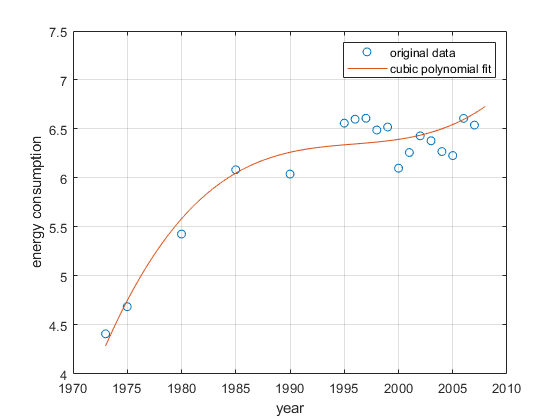

% x values for plotting
y_fit = polyval(a,x_pol); 
plot(year, energy,'o', x_pol, y_fit)
xlabel('year'), ylabel('energy consumption'),grid
legend('original data','cubic polynomial fit')

%residuals
r = zeros(2,19)

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:length(year)
    r(1,i) = y_fit(i);
    r(2,i) = ((y_fit(i)-energy(i)))^2;
end
r

r =     4.2863    4.3742    4.4594    4.5421    4.6222    4.6998    4.7750    4.8477    4.9181    4.9862    5.0520    5.1155    5.1768    5.2360    5.2930    5.3480    5.4009    5.4518    5.5007
    0.0153    0.0979    0.9382    2.3776    2.0102    3.4603    3.3307    3.1056    2.4708    2.3525    1.0984    1.3099    1.5704    1.3088    0.9545    0.7762    1.4571    1.1842    2.9593


r(2,:)

ans =     0.0153    0.0979    0.9382    2.3776    2.0102    3.4603    3.3307    3.1056    2.4708    2.3525    1.0984    1.3099    1.5704    1.3088    0.9545    0.7762    1.4571    1.1842    2.9593


sum(r(2,:))

ans = 32.7779

R = sqrt(sum(r(2,:)))

R = 5.7252